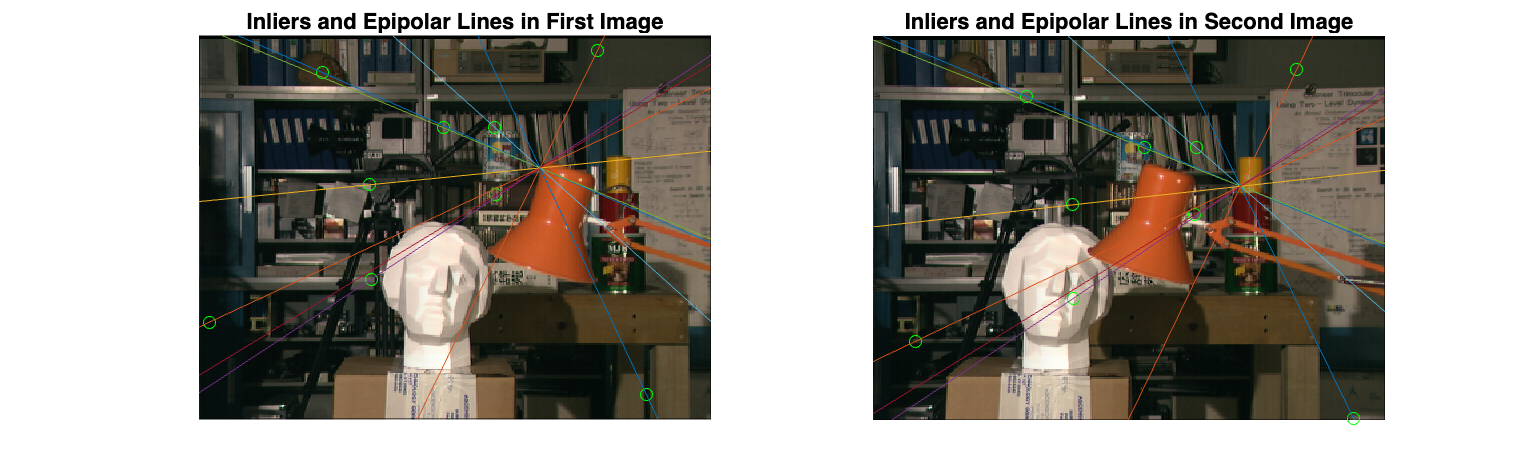

load stereoPointPairs
[fLMedS,inliers] = estimateFundamentalMatrix(matchedPoints1,...
    matchedPoints2,'NumTrials',4000);

I1 = imread('left.png');
figure; 
subplot(121);
imshow(I1); 
title('Inliers and Epipolar Lines in First Image'); hold on;
plot(matchedPoints1(inliers,1),matchedPoints1(inliers,2),'go')


epiLines = epipolarLine(fLMedS',matchedPoints2(inliers,:));
points = lineToBorderPoints(epiLines,size(I1));
line(points(:,[1,3])',points(:,[2,4])');


I2 = imread('right.png');
subplot(122); 
imshow(I2);
title('Inliers and Epipolar Lines in Second Image'); hold on;
plot(matchedPoints2(inliers,1),matchedPoints2(inliers,2),'go')
epiLines = epipolarLine(fLMedS,matchedPoints1(inliers,:));
points = lineToBorderPoints(epiLines,size(I2));
line(points(:,[1,3])',points(:,[2,4])');
truesize;